1.

A

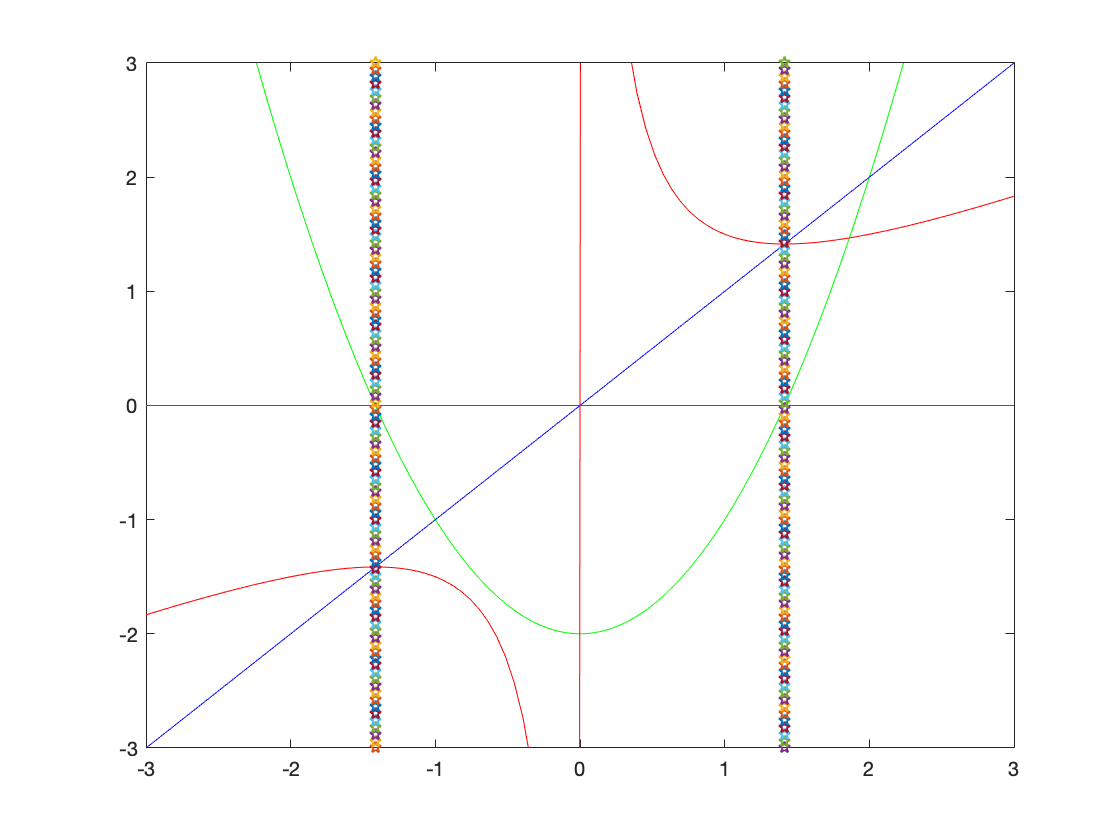

x=linspace(-3,3,100);
d=@(x) x.^2-2;
f = @(x) 0.5*(x+2/x);
g= @(x) cos(x);
[~,ps]=fp(f,1.5,5);
[~,rs]=bisection(d,1,2,eps) ;
%part i
plot(x,x.^2-2,'g',x,0.5*(x+2./x),'r',x,x,'b',x,x==0,-sqrt(2),x,'p',sqrt(2),x,'p');xlim([-3,3]);ylim([-3,3]);

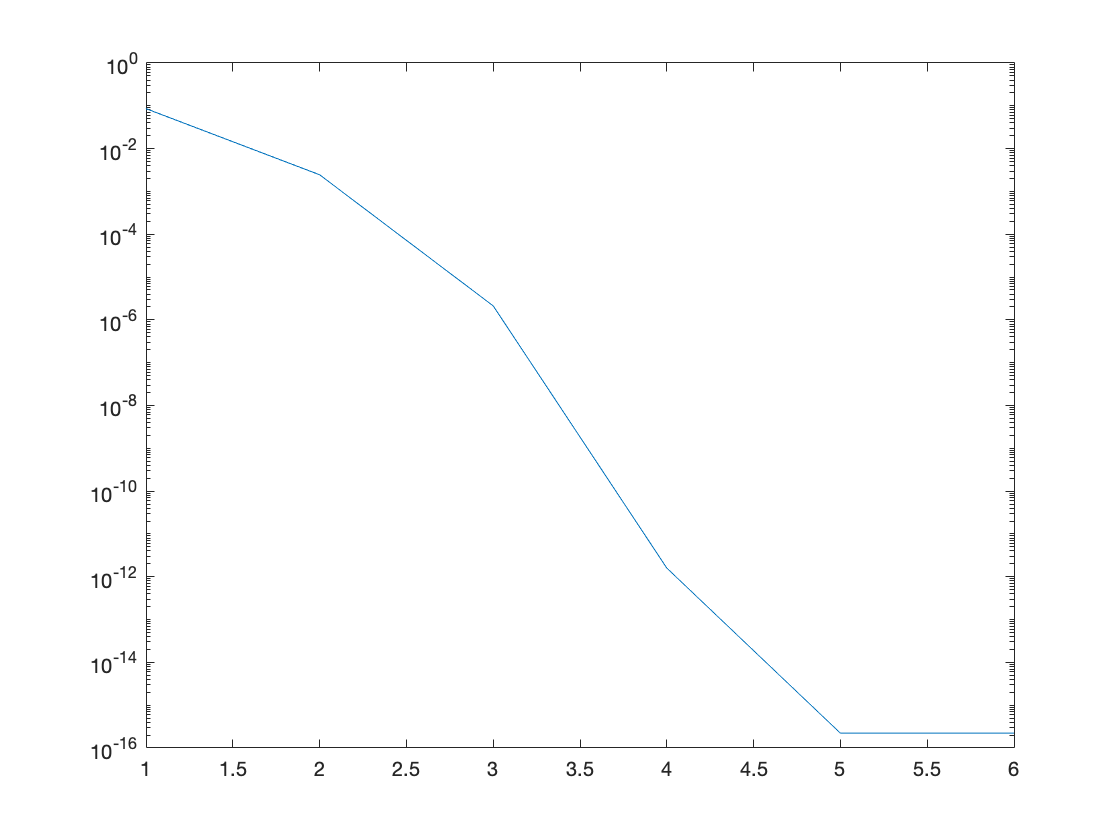

%part ii
%depending on the sign positive or negative

%part iii
semilogy(abs(sqrt(2)-ps))

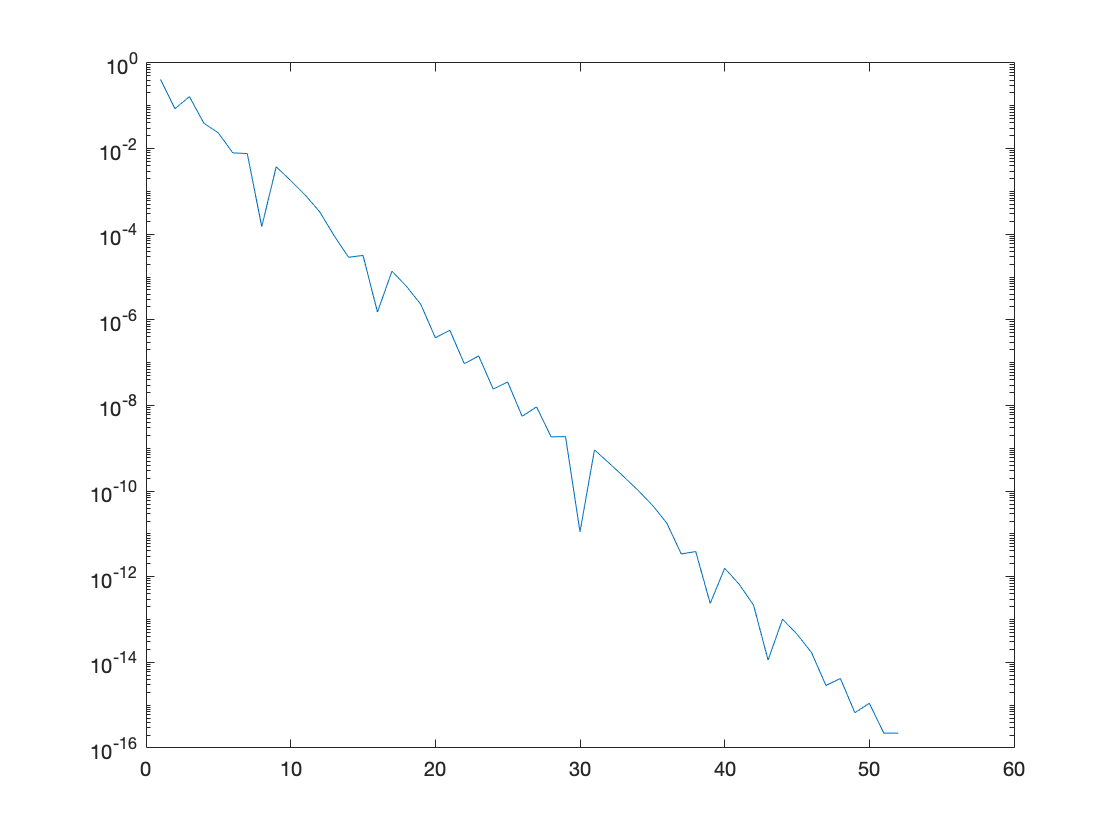

semilogy(abs(sqrt(2)-rs))

B

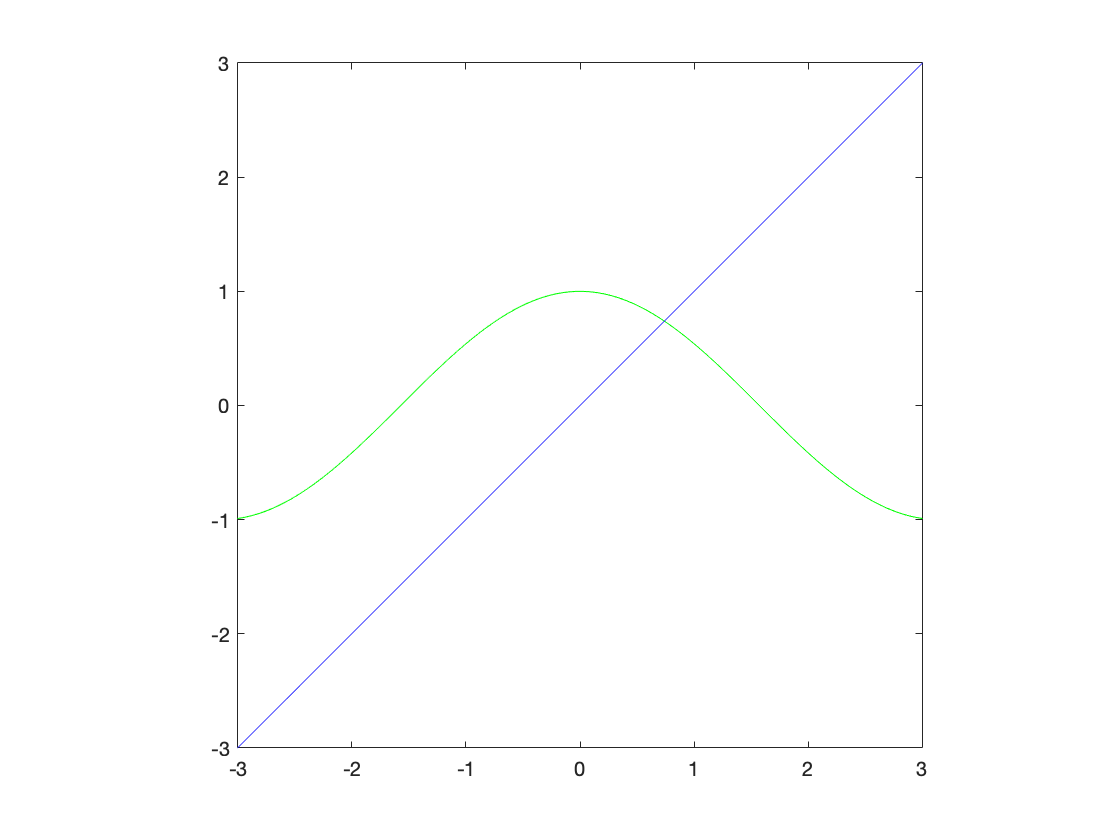

plot(x,cos(x),'g',x,x,'b'); axis square; xlim([-3,3]);ylim([-3,3]);

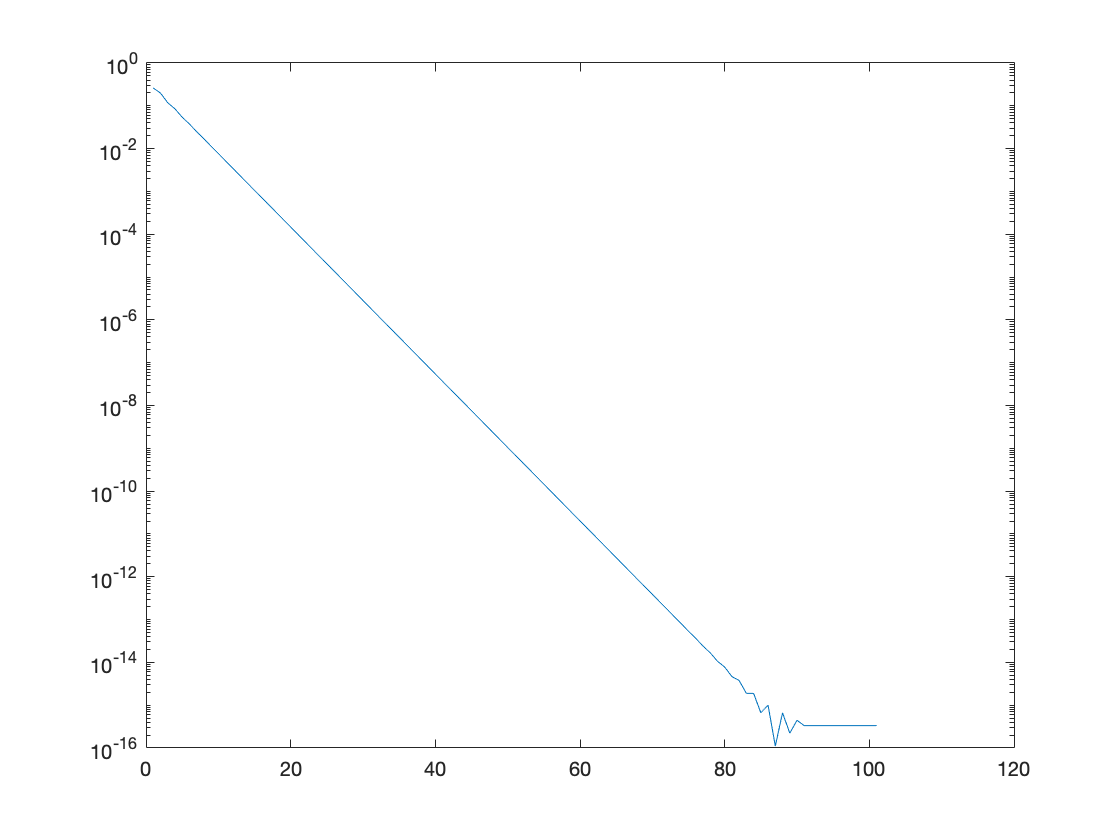

[~,gs]=fp(g,1,100);
semilogy(abs(0.739085133215161-gs))

C

g= @(x) 2*x ;
fp(g,0,10)

ans = 0

%converges only at p=0

D

g= @(x) [x(x~=1)/2,x(x==1)/x];
fp(g,2,10)

ans = 1

%it estimates at 1 but if it was infinitely precise it would estimate 0

Helper Functions

function [p,ps]= fp(g, p0, maxits)
%fixed point iteration on f
%p0 is starting iterate
%maxits is number of iterations
%p is result
p=p0;
ps=p;
for i=1:maxits
    p=g(p);
    %fprintf('After %d iterations\n',i,p)
    ps=[ps,p];
end
end

function [r,rs] = bisection(f, a, b, tol)
i=0;
rs=a;
while (abs(a - b) >= tol)
    i=i+1;
    assert(sign(f(a)) ~= sign(f(b)));
    c=(a+b)/2; %midpoint of interval
    
    if(b-a)/2<tol
       r=c;
       return;
    end

    if sign(f(a)) ~= sign(f(c))
        %root is left subinterval
        %fprintf('root is in the left subinterval\n');
        b=c; %a stays same
    else
        %root is right subinterval
        a=c; %b stays same
       %fprintf('root is in the right subinterval\n');
    end
r=c;
rs=[rs,r];
end
end